## **Lehrprogramm Robotertechnik**

**Eine Ausarbeitung von Mika Grüner, Luka Hrstic, Lukas Pelz und Marie Winkler**

Dieses Lehrprogramm zeigt verschiedene Möglichkeiten, wie man die Orientierung eines Körpers im dreidimensionalen Raum beschreiben kann:

- Richtungskosinusmatrix (RCM)

- Euler-Winkel (EW)

- Euler-Rodrigues-Parameter (ERP)

- Quaternionen

Es werden jeweils Vor- und Nachteile, numerische Aspekte, Rechenaufwand sowie Visualisierungen und Umrechnungen gezeigt.

 
% Dies ist ein Codeblock - ein Codeblock kann durch Klick auf den Run
% Button ausgeführt werden
%checkbox

ans = "one"

% Mithilfe einer Checkbox können verschiedene Funktionen an und abgewählt
% werden
"one"

ans =      0   100


% Mithilfe eines Drop-Down Menüs könnten verschiedene Optionen angewählt
% werden
[0 100]
% Mithilfe eines Range-Sliders könnten z.B. ausgewählt werden, auf wie
% viele Nachkommastellen gerundet wird oder ähnliches


### 1. Mathematische Grundlagen der Rotationsdarstellungen

In diesem Abschnitt werden die drei Methoden mathematisch beschrieben. Es werden jeweils die notwendigen Parameter, die Struktur sowie typische Anwendungen genannt.

Hier folgen Definitionen und Funktionen für:

- Richtungskosinusmatrix

- Euler-Winkel (inkl. Konventionen)

- Euler-Rodrigues-Parameter

- Quaternionen

% → Ziel: Verständliche Einführung mit Formeln und ggf. kurzen Beispielen.
% In diesem Abschnitt befinden sich auch schon alle Funktionen die im
% späteren Verlauf benötigt werden, um zwischen verschiedenen Darstellungen
% hin und her zu wechseln etc.


% % % Abschnitt 1: Richtungscosinusmatrix

% Berechne die Rotationsmatrix aus Einheitsvektoren, u,v,w
function R = calculate_rotation_matrix_RCM(u,v,w)
    R = [u(1), v(1), w(1);
         u(2), v(2), w(2);
         u(3), v(3), w(3)];
end

% Berechne die Parameter u,v,w aus einer gegebenen Rotationsmatrix
function [u,v,w] = calculate_uvw_from_RCM_rotation_matrix(R)
    u = R(:,1);
    v = R(:,2);
    w = R(:,3);

end

% % % Abschnitt 2: Euler-Winkel

% Berechne die Rotationsmatrix aus den Winkel phi theta und psi (rad)
function R = calculate_rotation_matrix_ew(phi,theta,psi)
    R = [ cos(psi)*cos(phi)-sin(psi)*cos(theta)*sin(phi),    cos(psi)*sin(phi)+cos(phi)*cos(theta)*sin(psi),    sin(theta)*sin(psi);
         -cos(phi)*sin(psi)-sin(phi)*cos(theta)*cos(psi),   -sin(psi)*sin(phi)+cos(psi)*cos(theta)*cos(phi),    sin(theta)*cos(psi);
          sin(phi)*sin(theta),                              -cos(phi)*sin(theta),                               cos(theta)        ];
end

% Berechne die Winkel aus einer gegebenen Rotationsmatrix
function q = calculate_q_from_ew_rotation_matrix(R)
    theta = acos(R(3,3));
    psi   = acos(R(2,3)/sin(theta));
    phi   = asin(R(3,1)/sin(theta));
    q=[phi; theta; psi];
end

% % % Abschnitt 3: Euler-Rodrigues Parameter

% Berechne die Rotationsmatrix aus den Parametern q
function R = calculate_rotation_matrix_erp(q)
    R = [ 2*q(1)^2 - 1 + 2*q(2)^2,     2*q(2)*q(3) - 2*q(1)*q(4),     2*q(2)*q(4) + 2*q(1)*q(3)  ;
          2*q(2)*q(3) + 2*q(1)*q(4),   2*q(1)^2 - 1 + 2*q(3)^2,       2*q(3)*q(4) - 2*q(1)*q(2)  ;
          2*q(2)*q(4) - 2*q(1)*q(3),   2*q(3)*q(4) + 2*q(1)*q(2),     2*q(1)^2 - 1 + 2*q(4)^2   ];
end

% Berechne die Parameter q aus einer gegebenen Rotationsmatrix
function q = calculate_q_from_erp_rotation_matrix(R)
    q0 = sqrt( ( R(1,1) + R(2,2) + R(3,3) + 1 ) / 4 );
    q1 = ( R(3,2) - R(2,3) ) / (4 * q0);
    q2 = ( R(1,3) - R(3,1) ) / (4 * q0);
    q3 = ( R(2,1) - R(1,2) ) / (4 * q0);
    q = [ q0 ; q1 ; q2 ; q3 ];
end

% % % Abschnitt 4: Quaternionen

% Berechne Multiplikation zweier Quaternionen
function Q = calculate_multiplication_quaternion(Q1,Q2)
    % perform quaternion multiplication according to script
    Q = [(Q1(1)*Q2(1)-Q1(2:4)*Q2(2:4)'),(Q1(1)*Q2(2:4) + Q2(1)*Q1(2:4) + cross(Q1(2:4),Q2(2:4)))];
end

% Berechne Rotation mit Quaternionen (Q * r * Q_n)
function r = calculate_rotation_quaternion(r,Q)
    r_quaternion = [0, r']; % creat mock quaternion from vektor
    Q_n = [Q(1),-Q(2),-Q(3),-Q(4)]; % create conjugate complex for rotation
    r = calculate_multiplication_quaternion( calculate_multiplication_quaternion(Q,r_quaternion), Q_n ); % perform two mulutiplications for rotation
    r = r(2:4)';
end

function q = calculate_quaternion_from_norm_and_angle(r_norm, angle)
    normAxis = r_norm ./ norm(r_norm);
    q0 = cos(angle / 2);
    q123 = normAxis .* sin(angle / 2);
    q = [q0; q123];
end

% % % Test-Abschnitt: In Abhängigkeit des gewählten Eintrag im
% % % Drop-Down-Menü wird eine Rotation ausgeführt

### 2. Visuelle Darstellung von Rotationen

Dieser Abschnitt zeigt die visuelle Umsetzung von Rotationen im Raum. Die Nutzer:innen sollen ein besseres Verständnis dafür bekommen, wie die verschiedenen Methoden dieselbe Rotation im Raum darstellen.

- Rotation um definierte Achse (z. B. z-Achse um 90°)

- Darstellung des Ursprungs- und Ziel-Koordinatensystems

- Darstellung mit Vektoren oder Achsen (quiver3, trplot etc.)

% → Ziel: Intuition aufbauen durch Animation oder statische Darstellungen.

### 3. Numerische Aspekte & Rechenverhalten

Dieser Abschnitt beleuchtet die Unterschiede bei numerischen Rechnungen:

- Rundungsfehler bei mehrfachen Rotationen

- Stabilität bei kleinen/mehrfachen Winkeln

- Speicherbedarf: Vergleich der Parameteranzahl

- Rechenzeit: Wie schnell kann eine Methode viele Rotationen durchführen?

% Beispiele:
% - In-Progress: 20-mal dieselbe Rotation anwenden → wie groß ist der Fehler am Ende?
% - Erledigt: Zeitmessung mit "tic" und "toc"
% - ToDo: Mehrere Rotationen verketten und dann auf Vektor anwenden
%     (Rotationen^Anzahl) auf Vektor
% - ToDo: Vergleichen mit mehreren (Rotationen auf Vektor) * Anzahl
% - ToDo: Simulation mit zufälligen Drehachsen

% → Ziel: Verständnis für numerische Grenzen und Performanzunterschiede.

Zunächst möchten wir veranschaulichen, wie sich Rundungsfehler auf mehrfache Rotationen auswirken. Ein numerisch stabiles Verfahren liefert auch bei kleinen Störungen wie einer begrenzten Genauigkeit oder bei Rundungsfehlern verlässliche und sinnvolle Ergebnisse.

r = [1;
     1;
     0    ];

plot_every_n_rotations = 100

n_rotations = 1000

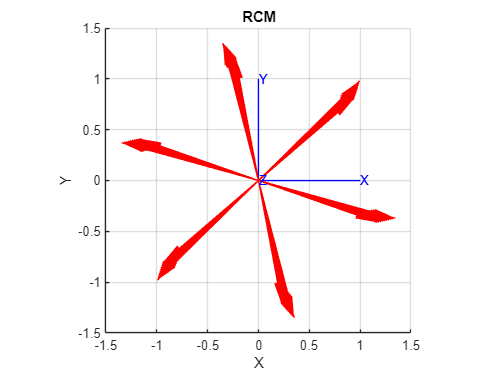

angle_deg = 60;
nachkommastellen_bei_rundung = 3;

 

% Setup
plot_every_n_rotations = 100%00;
n_rotations = 1000%00;
n_rotations_per_360_deg = 360 / angle_deg;

% Calculate required parameters for each approach
R_xyzuvw = rotz(deg2rad(angle_deg));

[u_rcm,v_rcm,w_rcm] = calculate_uvw_from_RCM_rotation_matrix(R_xyzuvw);
R_rcm = calculate_rotation_matrix_RCM(u_rcm,v_rcm,w_rcm);
R_ew = calculate_rotation_matrix_ew(deg2rad(angle_deg),0,0);
q = calculate_q_from_erp_rotation_matrix(R_xyzuvw);
R_erp = calculate_rotation_matrix_erp(q);

% Round rotation matrix 
R_rcm = round(R_rcm,nachkommastellen_bei_rundung);
R_ew  = round(R_ew ,nachkommastellen_bei_rundung);
R_erp = round(R_erp,nachkommastellen_bei_rundung);
q = round(q,nachkommastellen_bei_rundung);

% % % Abschnitt 1: Richtungscosinusmatrix
tranimate(eye(3));
title('RCM');
hold on;

r_rcm = r;
for z=1:n_rotations 

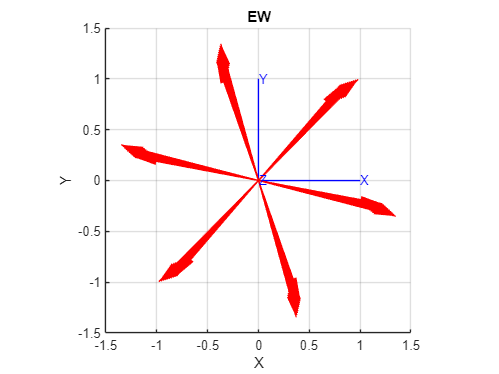

    for u=1:n_rotations_per_360_deg
        if(mod(z,plot_every_n_rotations)==0)
            plot_arrow([0;0;0],r_rcm,'r');
        end
        r_rcm = R_rcm * r_rcm;
    end
end
hold off;

% % % Abschnitt 2: Euler-Winkel
tranimate(eye(3));
title('EW');
hold on;

r_ew = r;
for z=1:n_rotations 

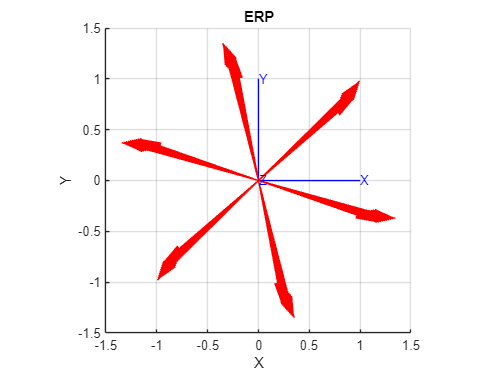

    for u=1:n_rotations_per_360_deg
        if(mod(z,plot_every_n_rotations)==0)
            plot_arrow([0;0;0],r_ew,'r');
        end
        r_ew = R_ew * r_ew;
    end
end
hold off;

% % % Abschnitt 3: Euler-Rodrigues Parameter
tranimate(eye(3));
title('ERP');
hold on;

r_erp = r;
for z=1:n_rotations 

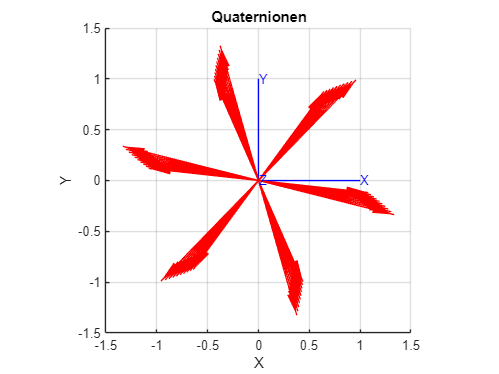

    for u=1:n_rotations_per_360_deg
        if(mod(z,plot_every_n_rotations)==0)
            plot_arrow([0;0;0],r_erp,'r');
        end
        r_erp = R_erp * r_erp;
    end
end
hold off;

% % % Abschnitt 4: Quaternionen
tranimate(eye(3));
title('Quaternionen');
hold on;

r_quat = r;
for z=1:n_rotations 

    for u=1:n_rotations_per_360_deg
        if(mod(z,plot_every_n_rotations)==0)
            plot_arrow([0;0;0],r_quat,'r');
        end
        r_quat = calculate_rotation_quaternion(r_quat,q');
    end
end
hold off;

n_parameters = 528000

Stabilität bei kleinen / mehrfachen Winkeln

%

Im anschließenden Codeblock möchten wir untersuchen, wie viel Speicherplatz die Parameter der verschiedenen Verfahren benötigen.

% Über den folgenden Slider kann bestimmt werden, für welche Anzahl von
% Parametern der benötigte Speicherplatz ausgegeben werden soll.

n_parameters =528000

% % % Abschnitt 1: Richtungscosinusmatrix

Array RCM_Parameters ist 36.2549 MB groß.


RCM_Parameters = zeros(n_parameters, 9);
for z = 1:n_parameters
    RCM_Parameters(z,:) = rand(9,1);
end

disp("Array RCM_Parameters ist " + sum(whos('RCM_Parameters').bytes) / 1024^2 + " MB groß.");


Array EW_Parameters ist 12.085 MB groß.


% % % Abschnitt 2: Euler-Winkel
EW_Parameters = zeros(n_parameters,3);
for z = 1:n_parameters
    EW_Parameters(z,:) = rand(3,1);
end
disp("Array EW_Parameters ist " + sum(whos('EW_Parameters').bytes) / 1024^2 + " MB groß.");


Array ERP_Parameters ist 16.1133 MB groß.


% % % Abschnitt 3: Euler-Rodrigues Parameter
ERP_Parameters = zeros(n_parameters,4);
for z = 1:n_parameters
    ERP_Parameters(z,:) = rand(4,1);
end
disp("Array ERP_Parameters ist " + sum(whos('ERP_Parameters').bytes) / 1024^2 + " MB groß.");


Array Quat_Parameters ist 16.1133 MB groß.


% % % Abschnitt 4: Quaternionen
Quat_Parameters = zeros(n_parameters,4);
for z = 1:n_parameters

anzahl_iterationen = 28000

    Quat_Parameters(z,:) = rand(4,1);
end
disp("Array Quat_Parameters ist " + sum(whos('Quat_Parameters').bytes) / 1024^2 + " MB groß.");

Zuletzt möchten wir untersuchen wie schnell Rotationen mithilfe der vier verschiedenen Ansätze durchgeführt werden können. Hierfür untersuchen wir eine Rotation um alle drei Achsen. Was vermuten Sie - welcher Ansatz lässt eine Rotation am effizientesten Berechnen?

anzahl_iterationen = 28000

q =     0.4945    0.6254    0.1104    0.5407


 

% Setup
r_init = [1.5 ; 2.3 ; 4.1];
q = rand(1,4,1)
[phi, theta, psi] = deal(rand()*2*pi, rand()*2*pi, rand()*2*pi);
u = randi(1, 3); v = randi(1, 3); w = randi(1, 3);

% % % Abschnitt 1: Richtungscosinusmatrix
function r_rotiert = calc_Computation_Time_RCM(u,v,w, r)
    R = calculate_rotation_matrix_RCM(u,v,w);
    r_rotiert = R * r;
end

% % % Abschnitt 2: Euler-Winkel
function r_rotiert = calc_Computation_Time_EW(phi,theta,psi, r)
    R = calculate_rotation_matrix_ew(phi,theta,psi);                % 3 Rotationen ??
    r_rotiert = R * r;
end

% % % Abschnitt 3: Euler-Rodrigues Parameter
function r_rotiert = calc_Computation_Time_ERP(q, r)
    R = calculate_rotation_matrix_erp(q);
    r_rotiert = R * r;
end

% % % Abschnitt 4: Quaternionen
function r_rotiert = calc_Computation_Time_Quat(q, r)
    r_rotiert = calculate_rotation_quaternion(r,q);
end

% % % Berechnung der benötigten Rechenzeit RCM
r = r_init;
tic;
for iterationen=1:anzahl_iterationen
    r = calc_Computation_Time_RCM(u,v,w, r);
end
elapsed_time_rcm = toc;

% % % Berechnung der benötigten Rechenzeit EW
r = r_init;
tic;
for iterationen=1:anzahl_iterationen
    r = calc_Computation_Time_EW(phi,theta,psi,r);
end
elapsed_time_ew = toc;

% % % Berechnung der benötigten Rechenzeit ERP
r = r_init;
tic;
for iterationen=1:anzahl_iterationen
    r = calc_Computation_Time_ERP(q,r);
end
elapsed_time_erp = toc;
 
% % % Berechnung der benötigten Rechenzeit Quaternionen
r = r_init;
tic;
for iterationen=1:anzahl_iterationen

Rechenzeit RCM mit 28000 Iterationen: 0.026505 Sekunden


    r = calc_Computation_Time_Quat(q,r);

Rechenzeit EW mit 28000 Iterationen: 0.077565 Sekunden


end

Rechenzeit ERP mit 28000 Iterationen: 0.039851 Sekunden


elapsed_time_quaternionen = toc;

Rechenzeit Quaternionen mit 28000 Iterationen: 0.22647 Sekunden



disp("Rechenzeit RCM mit " + anzahl_iterationen + " Iterationen: " + elapsed_time_rcm + " Sekunden");
disp("Rechenzeit EW mit " + anzahl_iterationen + " Iterationen: " + elapsed_time_ew + " Sekunden");
disp("Rechenzeit ERP mit " + anzahl_iterationen + " Iterationen: " + elapsed_time_erp + " Sekunden");
disp("Rechenzeit Quaternionen mit " + anzahl_iterationen + " Iterationen: " + elapsed_time_quaternionen + " Sekunden");

### 4. Interpolationsverhalten

Hier wird untersucht, wie gut sich die Methoden für Interpolation zwischen zwei Orientierungen eignen.

- Vergleich LERP (lineare Interpolation) vs. SLERP (sphärische Interpolation)

- Darstellung der interpolierten Zwischenorientierungen im Raum

- Fokus: Intuitivität und Glätte der Übergänge

% → Ziel: Zeigen, warum Quaternionen hier oft bevorzugt werden.

% Visueller Vergleich: Euler- vs. Quaternioneninterpolation von Laufbahnen
% Start- und Endorientierungen (in Euler-Winkeln – ZYX-Konvention)

eul_start = [0, pi/2, 0];           
eul_end   = [pi, -pi/2, pi];        

n = 100;
r = [0; 0; 1];  % Vektor zu drehen (Z-Achse)

% Speicher für Laufbahnen initialisieren
traj_euler = zeros(n, 3);
traj_quat  = zeros(n, 3);

% Start- und Endquaternionen berechnen
q_start = eul2quat(eul_start, 'ZYX');
q_end   = eul2quat(eul_end, 'ZYX');

for i = 1:n
    t = (i-1)/(n-1);
    
    % --- Euler-Interpolation ---
    eul_i = (1 - t)*eul_start + t*eul_end;
    R_euler = eul2rotm(eul_i, 'ZYX'); 
    traj_euler(i,:) = (R_euler * r)';
    
    % --- Quaternionen-Interpolation ---
    q_i = quatinterp(q_start, q_end, t, 'slerp');
    R_quat = quat2rotm(q_i);
    traj_quat(i,:) = (R_quat * r)';
    
end

% ----------- Laufbahnen plotten ----------------
figure('Name', 'Euler vs Quaternion Interpolation');
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Laufbahn der Spitze der Z-Achse während der Rotation');

% Trajektorien darstellen
plot3(traj_euler(:,1), traj_euler(:,2), traj_euler(:,3), 'r-', 'LineWidth', 2);
plot3(traj_quat(:,1), traj_quat(:,2), traj_quat(:,3), 'b--', 'LineWidth', 2);

% Legende und Referenzpunkt
legend('Euler-Interpolation', 'Quaternionen (SLERP)', 'Location', 'north');
%plot3(0,0,0,'ko','MarkerFaceColor','k');
view(3);

### 5. Kommutativität und Umkehrbarkeit

Dieser Abschnitt beleuchtet zwei wichtige Eigenschaften:

- Kommutativität: Was passiert, wenn man die Reihenfolge der Drehungen ändert?

- Umkehrbarkeit: Kann man aus einer Darstellung wieder exakt auf die ursprünglichen Parameter zurückrechnen?

% Tests:
% - Rotation A → Rotation B vs. B → A
% - Konvertierung: RCM → Euler → RCM und Vergleich mit Original

% → Ziel: Grenzen der Darstellungen aufzeigen, z. B. Gimbal Lock bei
% Euler-Winkeln oder nicht mögliche 180°-Drehung bei ERP

### 6. Umrechnungen zwischen den Darstellungen

In diesem Abschnitt wird gezeigt, wie man zwischen den Darstellungen konvertieren kann.

- RCM ↔ Euler-Winkel

- RCM ↔ Quaternion

- Euler ↔ Quaternion

- ... ?

% → Ziel: Verständnis für die Beziehung der Methoden untereinander

### 7. Zusammenfassung und Empfehlung

Hier wird eine übersichtliche Gegenüberstellung aller Methoden gegeben:

- Vor- und Nachteile (basierend auf eurer Tabelle)

- Empfehlungen je nach Anwendungsfall

- ggf. interaktive Entscheidungshilfe (z. B. Drop-Down-Menü mit Anwendungsszenario)

% → Ziel: Nachvollziehbare Zusammenfassung für Lernende